t_start = 0;
t_end = 1;
f_c = 5;
f_s = 100;

t_s = 1/f_s;
t = t_start: t_s:t_end-t_s; 
x = cos(2*pi*f_c*t);

plot(t,x);

xlabel("t")


v = 180;
R = 250;
beta = 0.3;
alpha = 0.5;
f_d = beta*v;
t_d =(2*R)/(3*10e8); 
y = alpha * cos(2*pi*(f_c+f_d)*(t-t_d));

plot(t, y);

xlim([0.000 1.000])
ylim([-0.50 0.50])
xlabel("t")

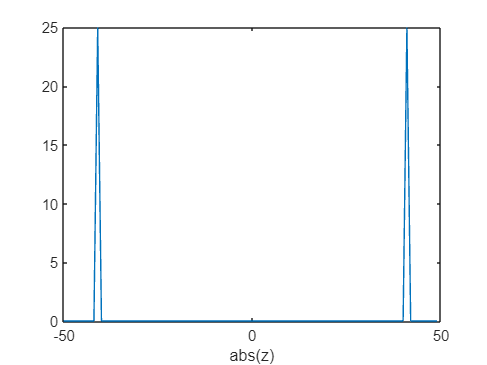


f=-f_s/2:1:(f_s/2)-1;
z = fftshift(fft(y));
plot(f, abs(z));

xlim([-50.0 50.0])
ylim([0.0 25.0])
xlabel("abs(z)")

plot(f, angle(z));

xlim([-50.0 50.0])
ylim([-4.00 4.00])
xlabel("angle(z)")


threshold_size = max(abs(z))/2;
[pks,locs] = findpeaks(abs(z),"Threshold",threshold_size)

pks =    25.0000   25.0000


locs =     10    92



phaz = zeros(size(locs));
for i = 1:size(locs,2); 
    phaz(i) =angle(z(locs(i)));
end


% محاسبه زمان پرواز از فاز
t_d_out = phaz(2) / (2 * pi * f_d)

t_d_out = 1.8210e-07


% محاسبه فاصله تخمینی
d_estimated = (3 * 10^8 * t_d_out) / 2

d_estimated = 27.3148

نویز سطح: 0.01


فرکانس داپلر تخمینی: 54.00 Hz


زمان پرواز تخمینی: -1.72e-05 s


فاصله تخمینی: -2574.17 m


نویز سطح: 0.05


فرکانس داپلر تخمینی: 54.00 Hz


زمان پرواز تخمینی: -1.96e-05 s


فاصله تخمینی: -2943.60 m


نویز سطح: 0.10


فرکانس داپلر تخمینی: 54.00 Hz


زمان پرواز تخمینی: 1.16e-04 s


فاصله تخمینی: 17380.43 m


نویز سطح: 0.20


فرکانس داپلر تخمینی: 54.00 Hz


زمان پرواز تخمینی: -7.87e-05 s


فاصله تخمینی: -11809.72 m


نویز سطح: 0.50


فرکانس داپلر تخمینی: 54.00 Hz


زمان پرواز تخمینی: -5.66e-05 s


فاصله تخمینی: -8488.38 m


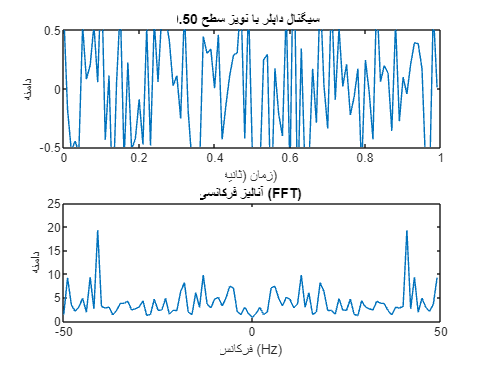

نویز سطح: 1.00


فرکانس داپلر تخمینی: 54.00 Hz


زمان پرواز تخمینی: 6.06e-03 s


فاصله تخمینی: 909535.39 m


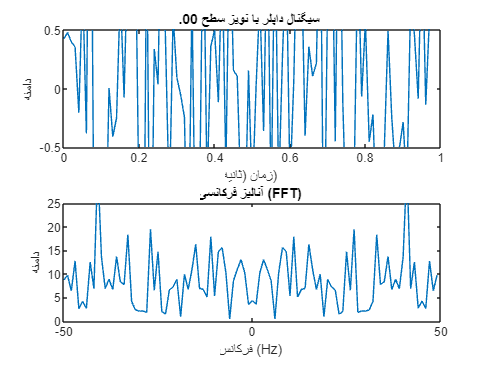



% سطح‌های مختلف نویز
noise_levels = [0.01, 0.05, 0.1, 0.2, 0.5, 1];

% تکرار تمرین برای سطح‌های مختلف نویز
for i = 1:length(noise_levels)
    noise_level = noise_levels(i);
    y_noisy = y + noise_level * randn(size(t)); % افزودن نویز به سیگنال

    % محاسبه FFT
    z = fftshift(fft(y_noisy));

    % پیدا کردن پیک‌های فرکانسی
    threshold_size = max(abs(z)) / 2;
    [pks, locs] = findpeaks(abs(z), "MinPeakHeight", threshold_size);

    % استخراج فاز پیک‌ها
    phaz = zeros(size(locs));
    for j = 1:length(locs)
        phaz(j) = angle(z(locs(j)));
    end

    % محاسبه زمان پرواز از فاز
    if length(phaz) >= 2
        t_d_out = phaz(2) / (2 * pi * f_d);
    else
        t_d_out = NaN; % اگر تعداد پیک‌ها کافی نباشد
    end

    % محاسبه فاصله تخمینی
    d_estimated = (3 * 10^8 * t_d_out) / 2;

    % نمایش نتایج
    fprintf('نویز سطح: %.2f\n', noise_level);
    fprintf('فرکانس داپلر تخمینی: %.2f Hz\n', f_d);
    fprintf('زمان پرواز تخمینی: %.2e s\n', t_d_out);
    fprintf('فاصله تخمینی: %.2f m\n', d_estimated);

    % نمایش سیگنال داپلر با نویز و FFT
    figure;
    subplot(2,1,1);
    plot(t, y_noisy);
    xlim([0 1]);
    ylim([-0.5 0.5]);
    xlabel("زمان (ثانیه)");
    ylabel("دامنه");
    title(sprintf('سیگنال داپلر با نویز سطح %.2f', noise_level));

    subplot(2,1,2);
    f = -f_s/2 : 1 : (f_s/2) - 1;
    plot(f, abs(z));
    xlim([-50 50]);
    ylim([0 25]);
    xlabel("فرکانس (Hz)");
    ylabel("دامنه");
    title("آنالیز فرکانسی (FFT)");
    endD